% Constants
g = 9.81;
y0 = 1.2;
v0 = 0;
l = 1.0;
k = 100;
m = 1;

% plot(out.numeric_position.Time, out.numeric_position.Data, 'r', 'LineWidth', 1.5)
% hold on
% plot(t, y, 'b', 'LineWidth', 1.5)
% hold off
% 
% xlabel('Time (s)')
% ylabel('Position (m)')
% ylim([0.6 1.3])
% %title('Numerical vs Analytical Position of Falling Mass')
% legend('Numerical', 'Analytical')
% grid on
% saveas(gcf, 'num_vs_ana.png')

%STEP SIZE
model = 'model';

% % Run with first step size
% set_param(model, 'SolverType', 'Fixed-step', 'FixedStep', '0.1');
% out1 = sim(model);
% 
% % Run with second step size
% set_param(model, 'FixedStep', '0.01');
% out2 = sim(model);
% 
% plot(out1.numeric_position.Time, out1.numeric_position.Data, 'r', 'LineWidth', 1.5)
% hold on
% plot(out2.numeric_position.Time, out2.numeric_position.Data, 'b', 'LineWidth', 1.5)
% %plot(out.numeric_position.Time, out.numeric_position.Data, 'r', 'LineWidth', 1.5)
% hold off
% 
% xlabel('Time (s)')
% ylabel('Position (m)')
% ylim([0.6 1.3])
% legend('0.1','0.01')
% grid on
% saveas(gcf, 'step_size.png')

%TOLERANCES

% Run with loose tolernces
set_param(model, ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'RelTol', '1e-1', ...
    'AbsTol', '1e-3');
out_loose = sim(model);


% Run with tight tolernces
set_param(model, ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'RelTol', '1e-6', ...
    'AbsTol', '1e-8');
out_tight = sim(model);

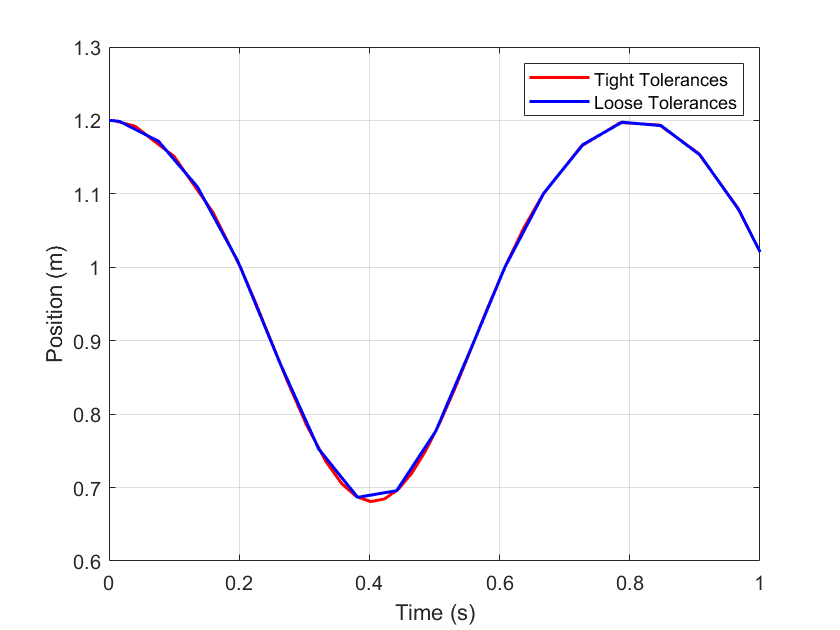


plot(out_tight.numeric_position.Time, out_tight.numeric_position.Data, 'r', 'LineWidth', 1.5)
hold on
plot(out_loose.numeric_position.Time, out_loose.numeric_position.Data, 'b', 'LineWidth', 1.5)
%plot(out.numeric_position.Time, out.numeric_position.Data, 'r', 'LineWidth', 1.5)
hold off

xlabel('Time (s)')
ylabel('Position (m)')
ylim([0.6 1.3])
xlim([0 1])
legend('Tight Tolerances','Loose Tolerances')
grid on
saveas(gcf, 'tolerances.png')